clc; clear variables; close all;

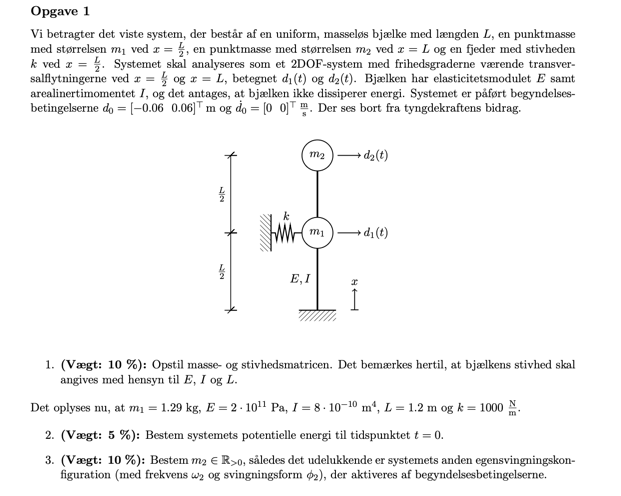

1.1 Idet vi betegner stivheden af bjælken $k_b$ kan vi vha. Newtons 2. lov opskrive


$$m_1 \ddot{d_1 } =-{\mathrm{kd}}_1 -k_b d_1 +k_b \left(d_2 -d_1 \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;\;\;\;\;\;\;m_1 \ddot{d_1 } +{\mathrm{kd}}_1 +{2k}_b d_1 -k_b d_2 =0$$



$$m_2 \ddot{d_2 } =-k_b \left(d_2 -d_1 \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;\;\;\;\;m_2 \ddot{d_2 } -k_b d_1 +k_b d_2 =0$$


Hvilket samles til


$$\left\lbrack \begin{array}{cc}
m_1  & 0\\
0 & m_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ddot{d_1 } \\
\ddot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
k+2k_b  & -k_b \\
-k_b  & k_b 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
d_1 \\
d_2 
\end{array}\right\rbrack =0$$


Stivheden af en bjælke mod transvers flytning er


$$k_b =\frac{3\mathrm{EI}}{L^3 }$$


Altså kan stivhedsmatricen regnes som

k = 1000; %N/m
E = 2e11; %Pa
I = 8e-10; %m^4
L = 1.2; %m

k_b = 3 * E * I / (L/2)^3;
K = [k+2*k_b    -k_b; -k_b    k_b];

Således


$$\begin{array}{l}
M=\left\lbrack \begin{array}{cc}
m_1  & 0\\
0 & m_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1\ldotp 29 & 0\\
0 & m_2 
\end{array}\right\rbrack \\
K=\left\lbrack \begin{array}{cc}
k+\frac{6\mathrm{EI}}{{\left(\frac{L}{2}\right)}^3 } & -\;\frac{3\mathrm{EI}}{{\left(\frac{L}{2}\right)}^3 }\\
-\;\frac{3\mathrm{EI}}{{\left(\frac{L}{2}\right)}^3 } & \;\frac{3\mathrm{EI}}{{\left(\frac{L}{2}\right)}^3 }
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
k+48\frac{\mathrm{EI}}{L^3 } & -24\frac{\mathrm{EI}}{L^3 }\\
-24\frac{\mathrm{EI}}{L^3 } & 24\frac{\mathrm{EI}}{L^3 }
\end{array}\right\rbrack 
\end{array}$$


1.2 Idet vi ser bort fra tyngdebidrag er det kun den elastiske potentielle energi der eksisterer i systemet.

Denne er


$$E_{\mathrm{pot}} =\frac{1}{2}{k\left(d\left(t\right)\right)}^2$$


$m_1$ er påvirket af tre paralelle fjedre (altså $k$ samt 2 $k_b$) således er den ækvivalente fjederkraft på $m_1$


$$k_1 =k+2k_b$$


Og for $m_2$ er den ækvivalente fjederkraft blot $k_b$. Altså

k_1 = k + 2*k_b;
k_2 = k_b;

d_0 = [-0.06; 0.06];

E_pot_1 = 1/2 * k_1 * d_0(1)^2;
E_pot_2 = 1/2 * k_2 * d_0(2)^2;

E_pot_tot = E_pot_1 + E_pot_2

E_pot_tot = 13.8000

Altså er den totale potentielle energi i systemet til $t = 0$, $E_{pot}(t = 0) = 13.8 J$

1.3 For at det kun er den anden egensvingningskonfiguration der bliver aktiveret kræver vi at egensvingningsform $\phi_2$ ligger parallelt med vores begyndelsesbetingelse. Såleds kræver vi

$\phi_{2,\mathrm{req}} =\left\lbrack \begin{array}{c}
-1\\
1
\end{array}\right\rbrack$.

Vi kan egensvingingskonfigurationen ved at løse egenværdi og egenvektorproblemerne


$$\det \left(K-{\omega_j }^2 M\right)=0$$



$$\left(K-{\omega_j }^2 M\right)\phi_j =0$$


Dette gøres I Matlab som:

syms m_2
m_1 = 1.29;

M = [m_1    0; 0    m_2];

[Phi, Lambda] = eig(M\K)

$$Phi = \left(\begin{array}{cc} \frac{1}{2}-\frac{\sqrt{60025\,{m_{2}}^{2}-11610\,m_{2}+16641}}{258}-\frac{245\,m_{2}}{258} & \frac{\sqrt{60025\,{m_{2}}^{2}-11610\,m_{2}+16641}}{258}-\frac{245\,m_{2}}{258}+\frac{1}{2}\\ 1 & 1 \end{array}\right)$$

$$Lambda = \left(\begin{array}{cc} \frac{10000\,\left(245\,m_{2}+\sqrt{60025\,{m_{2}}^{2}-11610\,m_{2}+16641}+129\right)}{1161\,m_{2}} & 0\\ 0 & \frac{10000\,\left(245\,m_{2}-\sqrt{60025\,{m_{2}}^{2}-11610\,m_{2}+16641}+129\right)}{1161\,m_{2}} \end{array}\right)$$

Her kan vi se at 


$$\phi_2 =\left\lbrack \begin{array}{c}
\frac{1}{2}-\frac{\sqrt{60025m_2^2 -11610m_2 +16641}\;}{258}-\frac{245m_2 }{258}\\
1
\end{array}\right\rbrack$$


Og dernæst kan vi løse for $m$ i $\phi_2 = \phi_{2,req}$ som

Phi_2_req = [-1; 1];

Phi_2 = [1/2 - (sqrt(60025 * m_2^2 - 11610 *m_2 + 16641)/258) - 245 *m_2/258; 1]

$$Phi\_2 = \left(\begin{array}{c} \frac{1}{2}-\frac{\sqrt{60025\,{m_{2}}^{2}-11610\,m_{2}+16641}}{258}-\frac{245\,m_{2}}{258}\\ 1 \end{array}\right)$$


m_2 = round(solve(Phi_2 == Phi_2_req, m_2), 4)

$$m\_2 = 0.7478$$

Altså har vi at


$$m_2 \approx 0,75$$


for at det udelukkende er systemets anden egensvingningskonfiguration der er aktiveret. 

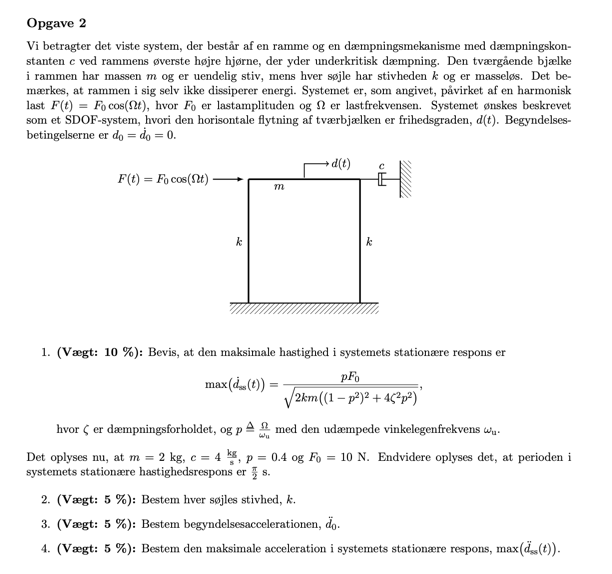

2.1 Vi har at det stationære respons er


$$d_p \left(t\right)=\frac{F_0 }{\sqrt{{\left(k-m\Omega^2 \right)}^2 +c^2 \Omega^2 }}\cos \left(\Omega t-\arctan \left(\frac{c\Omega }{k-m\Omega^2 }\right)\right)$$


Hvilket differentieres til

syms F_0 k m Omega c t zeta

dp = F_0/(sqrt((k-m*Omega^2)^2 +c^2*Omega^2)) * cos(Omega*t - atan(c*Omega/(k-m*Omega^2)));

ddp = diff(dp, t)

$$ddp = \frac{F_{0}\,\Omega \,\sin\left(\mathrm{atan}\left(\frac{\Omega \,c}{k-\Omega^{2}\,m}\right)-\Omega \,t\right)}{\sqrt{{\left(k-\Omega^{2}\,m\right)}^{2}+\Omega^{2}\,c^{2}}}$$

Altså er vores hastighed


$$\dot{d_p } =\frac{F_0 \Omega }{\sqrt{{\left(k-\Omega^2 m\right)}^2 +\Omega^2 c^2 }}\cdot \sin \left(\mathrm{atan}\left(\frac{\Omega c\;}{k-\Omega^2 m}\right)-\Omega t\right)$$


Dette er maksimeret når sinusleddet giver 1. Altså


$$\max \left(\dot{d_p } \right)=\frac{F_0 \Omega }{\sqrt{{\left(k-\Omega^2 m\right)}^2 +\Omega^2 c^2 }}$$


Vi bruger nu


$$p=\frac{\Omega }{\omega_u },\;\;\;\;\;\;\;\;\omega_u =\frac{c}{2m\zeta }\;\;\;\;\Rightarrow \;\;\Omega =\frac{p\;c}{2m\zeta }$$


Altså


$$\max \left(\dot{d_p } \right)=\frac{F_0 p\;c}{\sqrt{{\left(k-\frac{p^2 c^2 }{4m\zeta^2 }\right)}^2 +\frac{p^2 c^4 }{4m^2 \zeta^2 }}\cdot 2m\zeta }=\frac{{p\;F}_0 }{\sqrt{2\;k\;m\;\left({\left(1-p^2 \right)}^2 +4\zeta^2 p^2 \right)}}$$


2.2

Ovenfor er det vist at det stationære hastighedsrespons er


$$\dot{d_p } =\frac{F_0 \Omega }{\sqrt{{\left(k-\Omega^2 m\right)}^2 +\Omega^2 c^2 }}\cdot \sin \left(\mathrm{atan}\left(\frac{\Omega c\;}{k-\Omega^2 m}\right)-\Omega t\right)$$


Heri ser vi at vores periode er


$$p\left(\dot{d_p } \right)=2\Omega =\frac{\pi }{2}\;\;\;\Rightarrow \Omega =\frac{\pi }{4}$$


Vi har endvidere at


$$p=\frac{\Omega }{\omega_u }=0\ldotp 4\;\;\;\;\;\;\;\;\;\;\Rightarrow \omega_u =2\ldotp 5\cdot \frac{\pi }{4}$$


Vi har også at


$$\omega_u =\sqrt{\frac{k_{\mathrm{eq}} }{m}}\;\;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;\omega_u^2 \cdot m=k_{\mathrm{eq}} =2k\;\;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;\;k=\frac{m\omega_u^2 }{2}=2\ldotp 5\frac{m\pi }{8}$$


omega_u = 2.5 * pi/4;

m = 2;

k = m * omega_u^2/2

k = 3.8553

Altså er hver stivhedskonstant $k = 3.86 N/m$.

2.3 Vi har at


$$m\;\ddot{d_0 } +c\dot{d_0 } +k\;d_0 =F_o$$


Idet $\dot{d_0 } =d_0 =0$ får vi


$$m\;\ddot{d_0 } =F_0 \;\;\Rightarrow \ddot{d_0 } =\frac{F_0 }{m}$$


F_0 = 10; %N
m = 2; %kg


ddd_0 = F_0/m

ddd_0 = 5

Altså er vores begyndelsesacceleration $\ddot{d_0 } =5$

2.4 Vi har fra ovenfor at hastigheden i det stationære respons er


$$\dot{d_p } =\frac{F_0 \Omega }{\sqrt{{\left(k-\Omega^2 m\right)}^2 +\Omega^2 c^2 }}\cdot \sin \left(\mathrm{atan}\left(\frac{\Omega c\;}{k-\Omega^2 m}\right)-\Omega t\right)$$


Dette kan nu differentieres igen for at få accelerationen i det stationære resons

dddp = diff(ddp, t)

$$dddp = -\frac{F_{0}\,\Omega^{2}\,\cos\left(\mathrm{atan}\left(\frac{\Omega \,c}{k-\Omega^{2}\,m}\right)-\Omega \,t\right)}{\sqrt{{\left(k-\Omega^{2}\,m\right)}^{2}+\Omega^{2}\,c^{2}}}$$

Altså har vi vores accelerationsudtryk som:


$$\ddot{d} \left(t\right)=-\frac{F_0 \Omega^2 }{\sqrt{{\left(k-\Omega^2 m\right)}^2 +\Omega^2 c^2 }}\cos \left(\mathrm{atan}\left(\frac{\Omega c}{k-\Omega^2 m}\right)-\Omega \;t\right)$$


Dette er maksimeret når cosinusleddet er 1. Altså


$$\max \left(\ddot{d} \left(t\right)\right)=-\frac{F_0 \Omega^2 }{\sqrt{{\left(k-\Omega^2 m\right)}^2 +\Omega^2 c^2 }}$$


Omega = pi/4;
c = 4; %kg/s

dddp_max = abs(- F_0 * Omega^2/(sqrt(k-Omega^2 * m)^2 + Omega^2 * c^2))

dddp_max = 0.4938

Altså er den maksimale acceleration i det stationære respons

$\max \left(\ddot{d} \left(t\right)\right)=0\ldotp 494\;\frac{m}{s^2 }$.

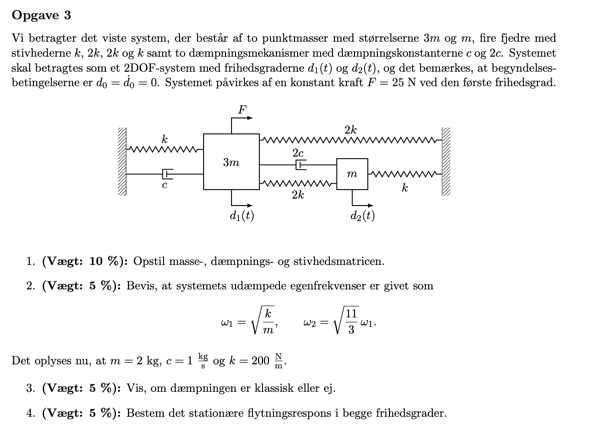

3.1 Fra Newtons 2. lov kan vi opstille


$$3m\ddot{d_1 } =-{\mathrm{kd}}_1 -{\mathrm{cd}}_1 -2{\mathrm{kd}}_1 +2k\left(d_2 -d_1 \right)+2c\left(\dot{d_2 } -\dot{d_1 } \right)\Rightarrow 3m\ddot{d_1 } +5{\mathrm{kd}}_1 -2{\mathrm{kd}}_2 -3c\dot{d_1 } +2c\dot{d_2 } =0$$



$$m\ddot{d_2 } =-2c\left(\dot{d_2 } -\dot{d_1 } \right)-2k\left(d_2 -d_1 \right)-{\mathrm{kd}}_2 \;\;\;\;\;\Rightarrow \;\;\;\;m\ddot{d_2 } +2c\dot{d_2 } -2c\dot{d_1 } +3{\mathrm{kd}}_2 -2{\mathrm{kd}}_1$$


Disse kan samles til


$$\left\lbrack \begin{array}{cc}
3m & 0\\
0 & m
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ddot{d_1 } \\
\ddot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
-3c & 2c\\
-2c & 2c
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{d_1 } \\
\dot{d_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
5k & -2k\\
-2k & 3k
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
d_1 \\
d_2 
\end{array}\right\rbrack =0$$


Altså har vi


$$\begin{array}{l}
M=\left\lbrack \begin{array}{cc}
3m & 0\\
0 & m
\end{array}\right\rbrack \\
C=\left\lbrack \begin{array}{cc}
-3c & 2c\\
-2c & 2c
\end{array}\right\rbrack \\
K=\left\lbrack \begin{array}{cc}
5k & -2k\\
-2k & 3k
\end{array}\right\rbrack 
\end{array}$$


3.2 Vores karakteristiske ligning er


$$\det \left(K-\omega^2 M\right)=0$$



$$\det \left(\left\lbrack \begin{array}{cc}
5k-\omega^2 3m & -2k\\
-2k & 3k-\omega^2 m
\end{array}\right\rbrack \right)=0$$
 

Hvilket vi løser i MatLab som:

syms k omega m c positive
M = [3*m 0; 0 m];
K = [5*k  -2*k; -2*k   3*k];

% Karakteritisk ligning: det(K - omega^2 M) = 0
char_eq = det(K - omega^2*M);

% Solve for omega
omega_sol = solve(char_eq == 0, omega)

$$omega\_sol = \left(\begin{array}{c} \frac{\sqrt{k}}{\sqrt{m}}\\ \frac{\sqrt{33}\,\sqrt{k}}{3\,\sqrt{m}} \end{array}\right)$$

Altså er det vist.

3.3 For klassisk dæmpning kræver vi at $\tilde{C}$ er diagonal, hvor


$$\tilde{C} =\Phi^T C\Phi$$


Idet $\Phi$ er modalmatricen. Denne findes I Matlab ved at løse egenvektoproblemet


$$\left(K-{\omega_j }^2 M\right)\phi_j =0$$


for hver af vores egenværdier. Dette gøres I Matlab som

C = [-3*c  2*c;  -2*c  2*c];

[Phi, Lambda] = eig(M\K);

Phi

$$Phi = \left(\begin{array}{cc} 1 & -\frac{1}{3}\\ 1 & 1 \end{array}\right)$$

Altså er vores modalmatrice


$$\Phi =\left\lbrack \begin{array}{cc}
1 & -\frac{1}{3}\\
1 & 1
\end{array}\right\rbrack$$


C_tilde = Phi' * C * Phi

$$C\_tilde = \left(\begin{array}{cc} -c & \frac{17\,c}{3}\\ \frac{c}{3} & \frac{5\,c}{3} \end{array}\right)$$

Altså får vi vores modale dæmpningsmatrice


$$\tilde{C} =\left\lbrack \begin{array}{cc}
-c & \frac{17c}{3}\\
\frac{c}{3} & \frac{5c}{3}
\end{array}\right\rbrack$$


Denne er kun diagonal for $c = 0$ og da $c=1$ har vi at dæmpningen ikke er klassisk. 

3.4

Idet den påførte kraft er konstant vil flytningen blot være


$$d_{\mathrm{ss}} =\frac{F}{k_{\mathrm{eq}} }$$


Dette regnes på matriceform i Matlab som

F_0 = [25; 0];

k_num = 200;

K_num = subs(K, k, k_num);

dss = round(K_num\F_0, 4)

$$dss = \left(\begin{array}{c} 0.0341\\ 0.0227 \end{array}\right)$$

Altså  bliver de to stationære flytninger $d_{\mathrm{ss}}^{\left(1\right)} =0\ldotp 034m,\;\;d_{\mathrm{ss}}^{\left(2\right)} =0\ldotp 023m$

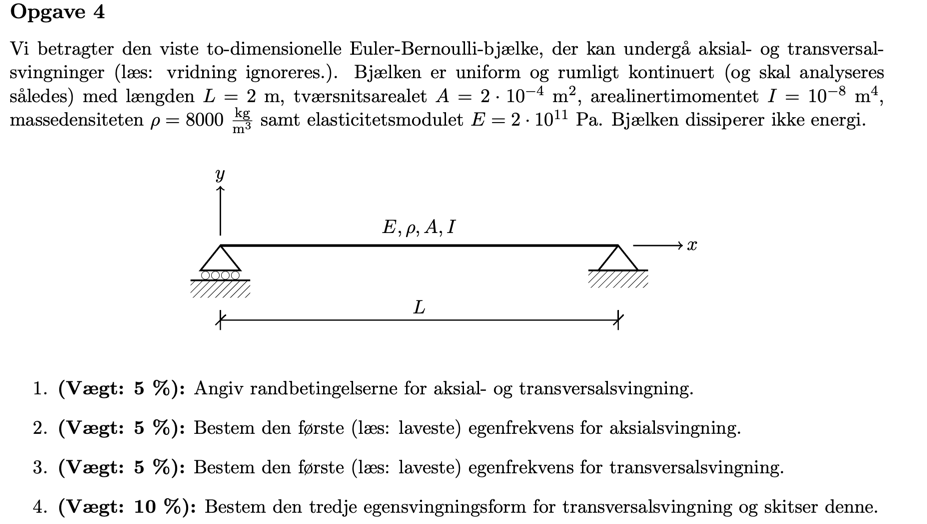

4.1 Euler Bernoulli transversalsvingning er 4. orden i $x$ og vi skal derfor have 4 randbetingelser for $\varphi_y$. Aksialsvingning er kun 2. orden og vi skal derfor kun have 2 randbetingelser for $\varphi_x$. Højre forhindrer aksial bevægelse


$$\varphi_x \left(L,t\right)=0\;\;\;\Rightarrow \;\phi_j^x \left(L\right)=0$$


Og den venstre kræver 0 tøjning:


$$\frac{d\varphi_x }{x}\left(0,t\right)=0\;\;\;\Rightarrow \;\frac{d\phi_j^x }{x}\left(0\right)=0$$


Dermed er vores randbetingelser for aksialsvingning $\phi_j^x$


$$\frac{d\phi_j^x }{x}\left(0\right)=0,\;\;\;\;\;\;\phi_j^{\left(x\right)} \left(L\right)=0$$


Begge understøtninger forhindrer transversal bevægelse så:


$$\varphi_y \left(0,t\right)=0\;\;\;\Rightarrow \;\;\phi_j^y \left(0\right)=0$$
 


$$\varphi_y \left(L,t\right)=0\;\;\;\Rightarrow \;\;\phi_j^y \left(L\right)=0$$
 

Ingen af dem modstår et moment i transversalsvingningen så vi har også:


$$\frac{d^2 \varphi_y \left(0,t\right)}{x^2 }=0\;\;\;\Rightarrow \frac{d^2 \phi_j^y \left(0\right)\;\;\;}{x^2 }=0$$



$$\frac{d^2 \varphi_y \left(L,t\right)}{x^2 }=0\;\;\;\Rightarrow \frac{d^2 \phi_j^y \left(L\right)\;\;\;}{x^2 }=0$$


Altså er vores randbetingelser for transversalsvingningen $\phi__j^y$:

 
$$\phi_j^y \left(0\right)=0\;\;\;\;\;\;\;\;\;\phi_j^y \left(L\right)=0\;\;\;\;\;\;\;\;\frac{d^2 \phi_j^y \left(0\right)\;\;\;}{x^2 }=0\;\;\;\;\;\;\;\;\;\frac{d^2 \phi_j^y \left(L\right)\;\;\;}{x^2 }=0$$


Således:


$$\frac{d\phi_j^x }{x}\left(0\right)=0,\;\;\;\;\;\;\phi_j^{\left(x\right)} \left(L\right)=0$$


 
$$\phi_j^y \left(0\right)=0\;\;\;\;\;\;\;\;\;\phi_j^y \left(L\right)=0\;\;\;\;\;\;\;\;\frac{d^2 \phi_j^y \left(0\right)\;\;\;}{x^2 }=0\;\;\;\;\;\;\;\;\;\frac{d^2 \phi_j^y \left(L\right)\;\;\;}{x^2 }=0$$


4.2 Den generelle løsning er


$$\phi_j^y \left(x\right)=A_j^{\left(1\right)} \cos \left(\frac{\omega_j }{\eta }x\right)+A_j^{\left(2\right)} \sin \left(\frac{\omega_j }{\eta }x\right)$$


Fra $\frac{d\phi_j^x }{x}\left(0\right)=0$ har vi at


$$A_j^{\left(2\right)} =0$$


Så


$$\phi_j^y \left(x\right)=A_j^{\left(1\right)} \cos \left(\frac{\omega_j }{\eta }x\right)$$


Fra $\;\phi_j^x \left(L\right)=0$ har vi at


$$\frac{\omega_j }{\eta \;}L=\pi \;j-\frac{\pi }{2}$$


Altså


$$\omega_j =\frac{\left(\pi \;j-\frac{\pi }{2}\right)\eta }{L}=\frac{\left(\pi \;j-\frac{\pi }{2}\right)}{L}\sqrt{\frac{E}{\rho }}$$


Den laveste vinkelegenfrekvens er for $j = 1$ så

L = 2; %m
E = 2e11; %Pa
rho = 8000; %kg/m^3

omega_1_x = (pi/2)/L * sqrt(E/rho)

omega_1_x = 3.9270e+03

Altså er den laveste egenfrekvens for aksialsvinging $\omega_1 \approx 3927$ rad/s. 

4.3 For transversalsvinging er vores generelle løsning


$$\phi_j^y \left(x\right)=A_j^{\left(1\right)} \cos \left(\epsilon_j x\right)+A_j^{\left(2\right)} \sin \left(\epsilon_j x\right)+A_j^{\left(3\right)} \cosh \left(\epsilon_j x\right)+A_j^{\left(4\right)} \sinh \left(\epsilon_j x\right)$$


hvor


$$\epsilon_j =\sqrt{\frac{\omega_j }{\eta \;}}$$
 

med

 $\eta =\sqrt{\frac{E\;I}{\rho \;A}}$. 

Vi har ligeledes vores randbetingelser:

 
$$\phi_j^y \left(0\right)=0\;\;\;\;\;\;\;\;\;\phi_j^y \left(L\right)=0\;\;\;\;\;\;\;\;\frac{d^2 \phi_j^y \left(0\right)\;\;\;}{x^2 }=0\;\;\;\;\;\;\;\;\;\frac{d^2 \phi_j^y \left(L\right)\;\;\;}{x^2 }=0$$


Fra $\phi_j^y \left(0\right)=0\;$ har vi


$$0=A_1^{\left(1\right)} +A_1^{\left(3\right)}$$


og fra $\frac{d^2 \phi_j^y \left(0\right)\;\;\;}{x^2 }=0$ har vi


$$0=-A_1^{\left(1\right)} +A_1^{\left(3\right)}$$


Altså har vi $A_1^{\left(1\right)} =A_1^{\left(2\right)} =0$. Dermed bliver vores generelle løsning reduceret til


$$\phi_j \left(x\right)=A_1^{\left(2\right)} \sin \left(\epsilon_j x\right)+A_1^{\left(4\right)} \sinh \left(\epsilon_j x\right)$$


De to resterende randbetingelser yder


$$\phi_j \left(L\right)=0=A_1^{\left(2\right)} \sin \left(\epsilon_j L\right)+A_1^{\left(4\right)} \sinh \left(\epsilon_j L\right)$$



$$\frac{d^2 \phi_j \left(L\right)}{x^2 }=0\;\Rightarrow 0=-A_1^{\left(2\right)} \sin \left(\epsilon_j L\right)+A_1^{\left(4\right)} \sinh \left(\epsilon_j L\right)$$


Disse giver umiddelbart 


$$A_1^{\left(2\right)} =A_1^{\left(4\right)} =0$$


omend dette ikke kan være rigtigt, da dette antyder stivlegemebevægelse idet alle $A_1^{(i)} = 0$ og derfor $\phi_1 =0$ i dette tilfælde, hvilket ikke kan lade sig gøre.

Vi prøver derfor istedet noget andet. Vi har


$$\epsilon_j =\sqrt{\frac{\omega_j^y }{\eta \;}}\;\Rightarrow \omega_j^y =\epsilon^2 \eta \;$$


og


$$\eta =\sqrt{\frac{\textrm{EI}}{\rho \;A}}$$


Vi har fra opgaven at


$$\phi_j^y \left(x\right)=\sin \left(\frac{j\pi \;x}{L}\right)$$


hvorfor vi ved at


$$\epsilon_j =\frac{\;j\pi \;}{L}\;\;\;\Rightarrow \;\phi_j^y \left(x\right)=\sin \left(\epsilon_j x\right)$$


Vi får dermed at


$$\omega_j^y =\frac{j^2 \pi^2 }{L^2 }\eta =\frac{j^2 \pi^2 }{L^2 }\sqrt{\frac{\mathrm{EI}}{\rho \;A}}\;\;\;\Rightarrow \;\;\;\;\;\omega_1^y =\frac{\pi^2 }{L^2 }\sqrt{\frac{\mathrm{EI}}{\rho \;A}}$$


Altså

I = 1e-8; %m^4
A = 2e-4; %m^2

omega_1_y = pi^2/L^2 * sqrt(E * I/(rho * A))

omega_1_y = 87.2358

Altså er den laveste egenfrekvens for transversalsvingning


$$\omega_1^y =87\ldotp 236\;\frac{\mathrm{rad}}{s}$$


4.4 Egensvingningsformerne for transversalsvingingen med vores randbetingelser er


$$\phi_j \left(x\right)=\sin \left(\frac{j\pi x}{L}\right),j=1,2,\ldots$$


Så den trejde egensvingingsform er


$$\phi_3 \left(x\right)=\sin \left(\frac{3\pi }{2}\;x\right)$$